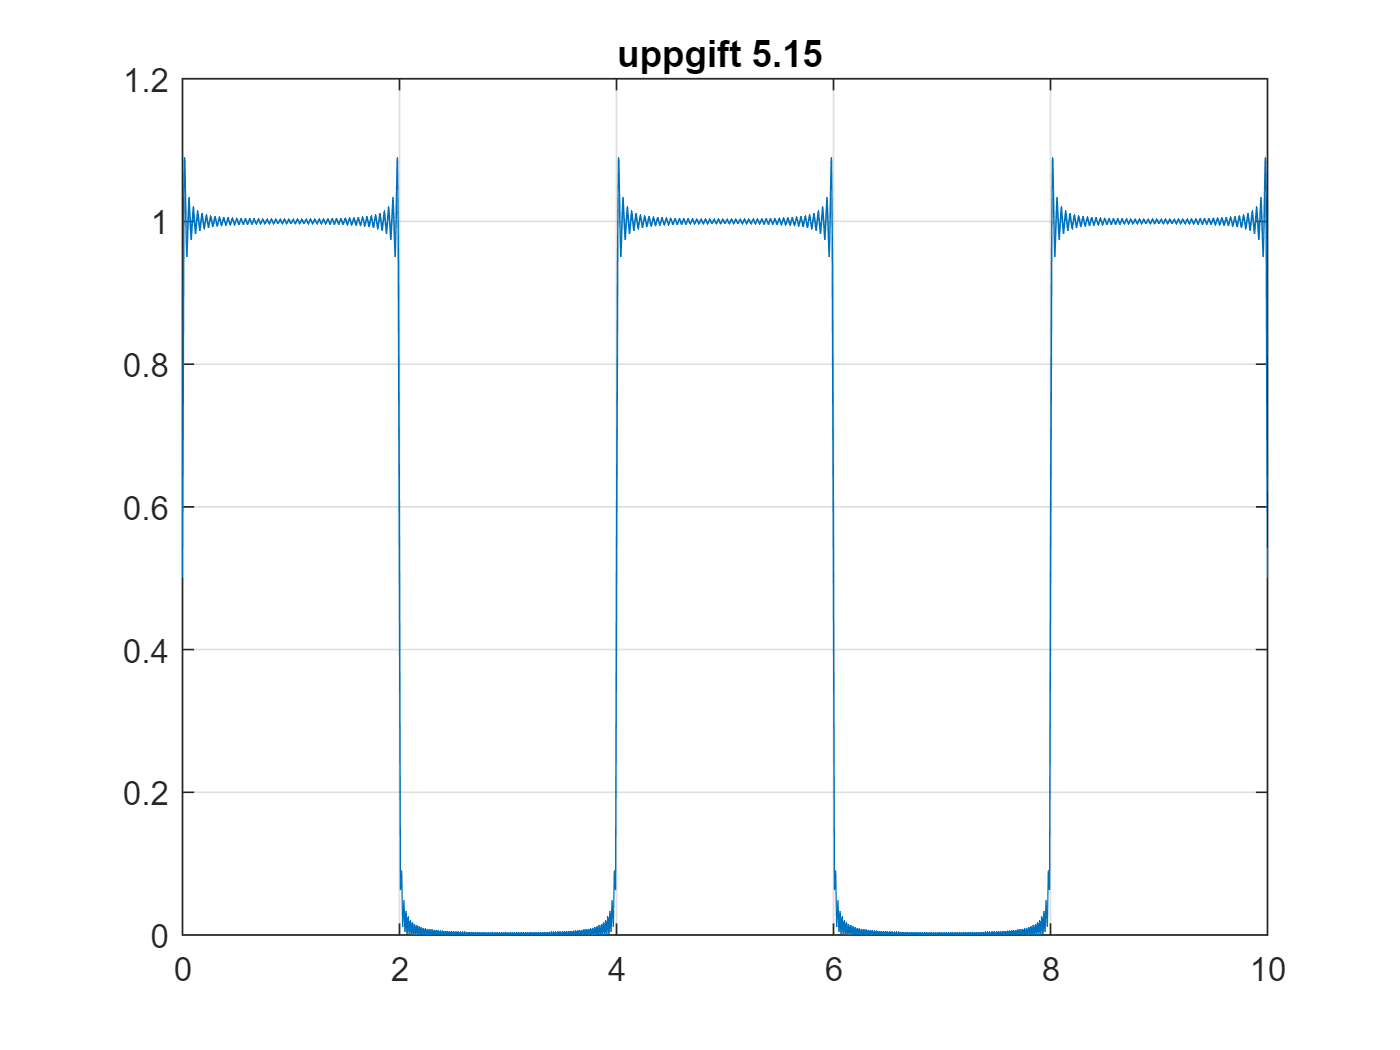

%5.15

T=4;
a=2;
i=0;
% Välj ett lämpligt intervall för tiden t
for t1=0:0.01:10
 i=i+1;
 t(i)=t1; % Spara tiden i vektorn t
 x1=0; % Nollställ summeringen
 
 
% Välj ett lämpligt intervall för k, stegintervall 1
for k=-100:1:100      
    if k==0
    c0=a/T; % Här beräknas c0
    else
        ck=(-1/(1i*k*2*pi))*(exp(-1i*k*2*pi*a/T)-1); 
        x1=x1 + ck*exp(1i*k*2*pi*t1/T); % Summera F.serien
     end 
 end
x(i)=c0+x1; % Här får vi hela F.serien inkl. c0 
end % Fortsätt med nästa t fram till t=10
% Rita ut Fourierserien
figure; 
plot(t, abs(x));
grid on;
title('uppgift 5.15 ');


% a) + b) vi ser att ju större k blir desto mer exakt blir summan, dvs Fourierserien
%ty vi summerar över fler termer 


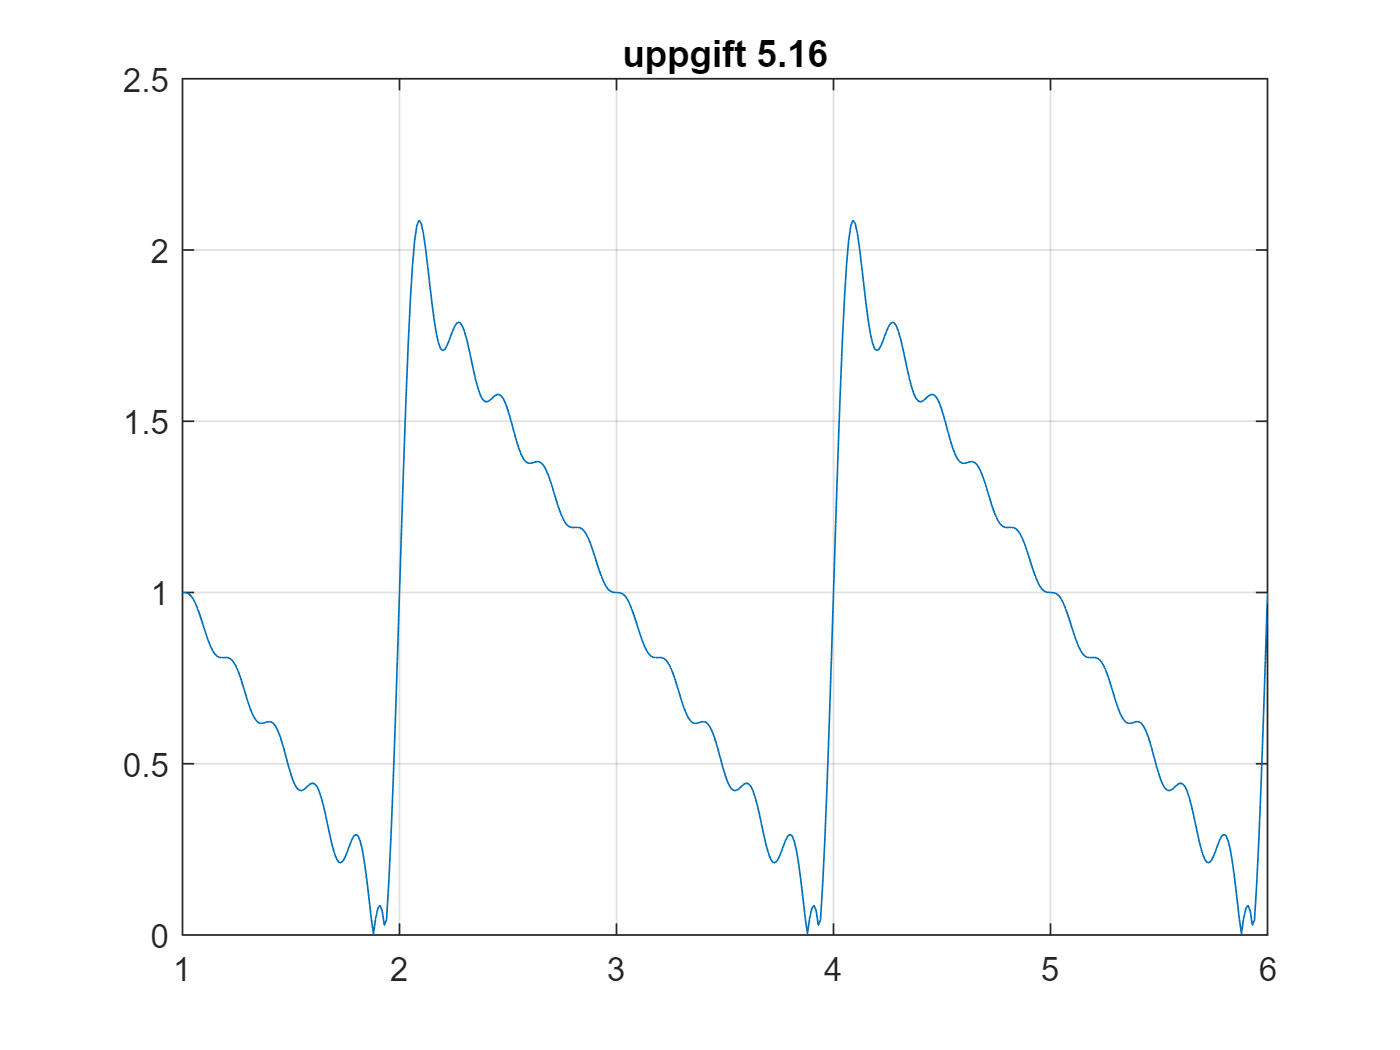

%5.16
clear 

i =1; %startvärdet 
TT = 2; %perioden 
a = 2; 

%stega t mellan 1 och 6 sekunder med steget 0.01
for t1 = 1:0.01:6
    x1 = 0; %nollställ summeringen

 %stega igenom med intervall k för summeringen av summan = fourierserien '
 for k = -10:1:10 
     if k == 0
         %beräkna c0 
         c0 = a/TT; 
     else 
         %beräkna Fourierkoefficienter 
         ck = (1/(1i*k*pi)); 
         %beräkna termer i serien 
         x1 = x1 + ck*(exp(1i*k*pi*t1)); 
     end
 end
 %erhåll hela serien, inklusive c0 
x(i) = c0 + x1; 
t2(i) = t1; %spara tiden i vektorn t
i = i+1; 
end

%plotta serien 
figure; 
plot(t2, abs(x)); 
grid on;
title('uppgift 5.16');

%den beräknade approximationen i grafen ovan helt ok, liknar den exakta
%bilden av serien men långt ifrån exakt 


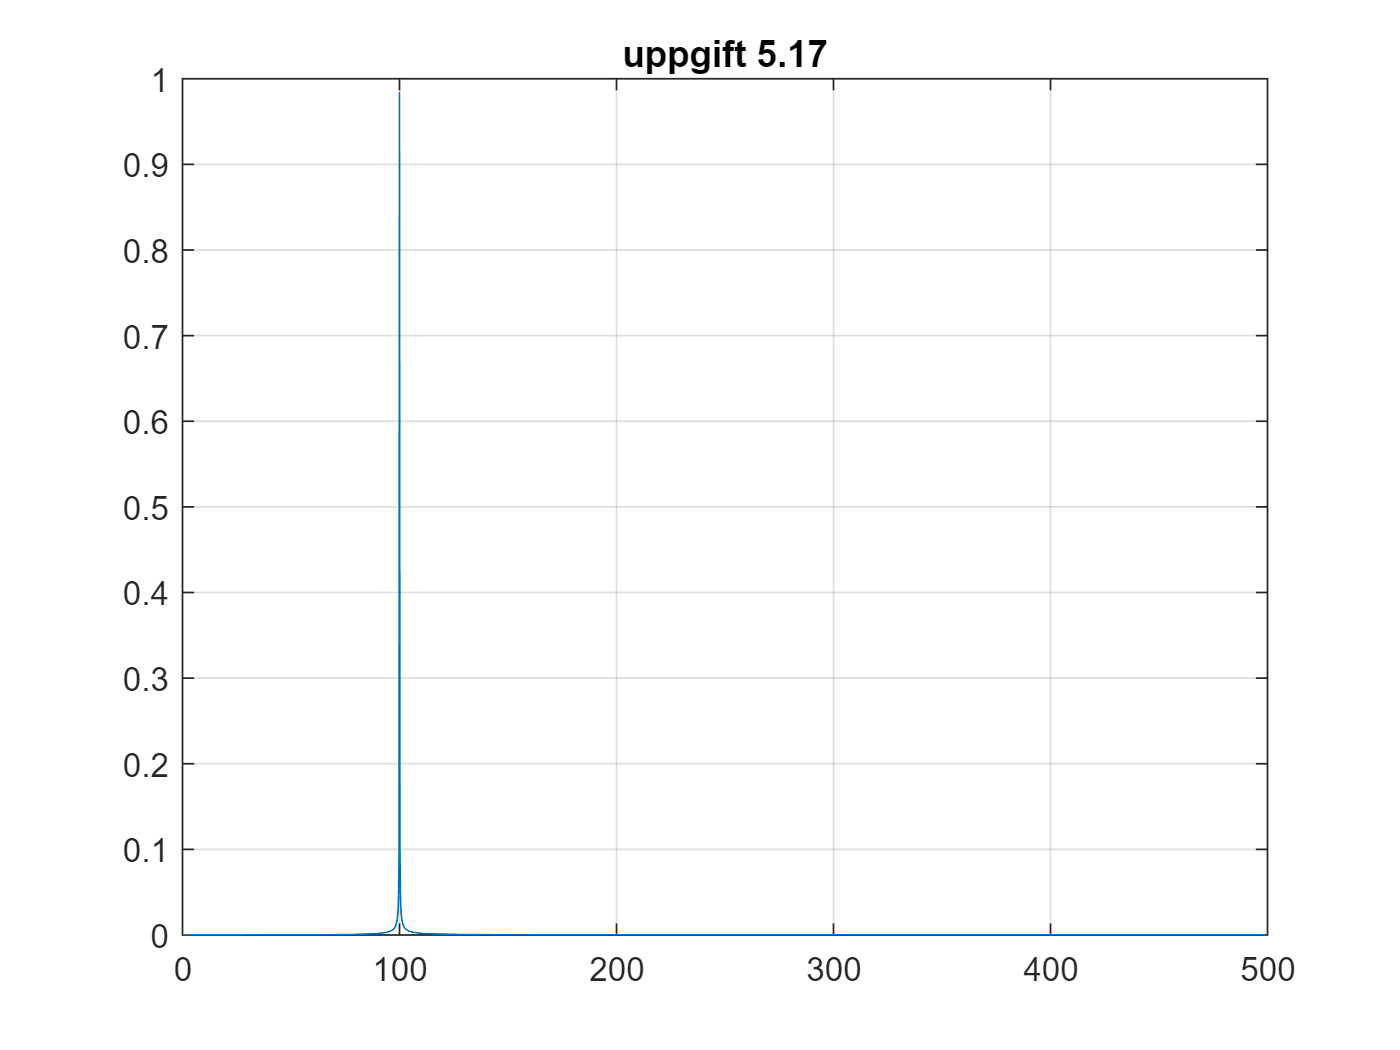

clear 
%5.17 

A=1.0; f_signal=100; f_sampl=1000;
t=0:(1/f_sampl):5; % Skapa en tidvektor t,sampl.frekv=1000 Hz
% Hur många sampel blir det ? (N)
N=size(t,2); 
% Skapa signalen x(t)
x=A*sin(2*pi*f_signal.*t);
% Fouriertransformera via FFT (den diskreta varianten)
X=fft(x);
% Skapa en frekvensaxel med korrekt delning (steg)
f=0:(f_sampl/N):f_sampl/2;
% Hur många frekvenssteg blir det ? (M)
M=size(f,2);
% Rita ut resultat
plot(f,abs(X(1:M))/2501);
grid on
title(['uppgift 5.17']); 

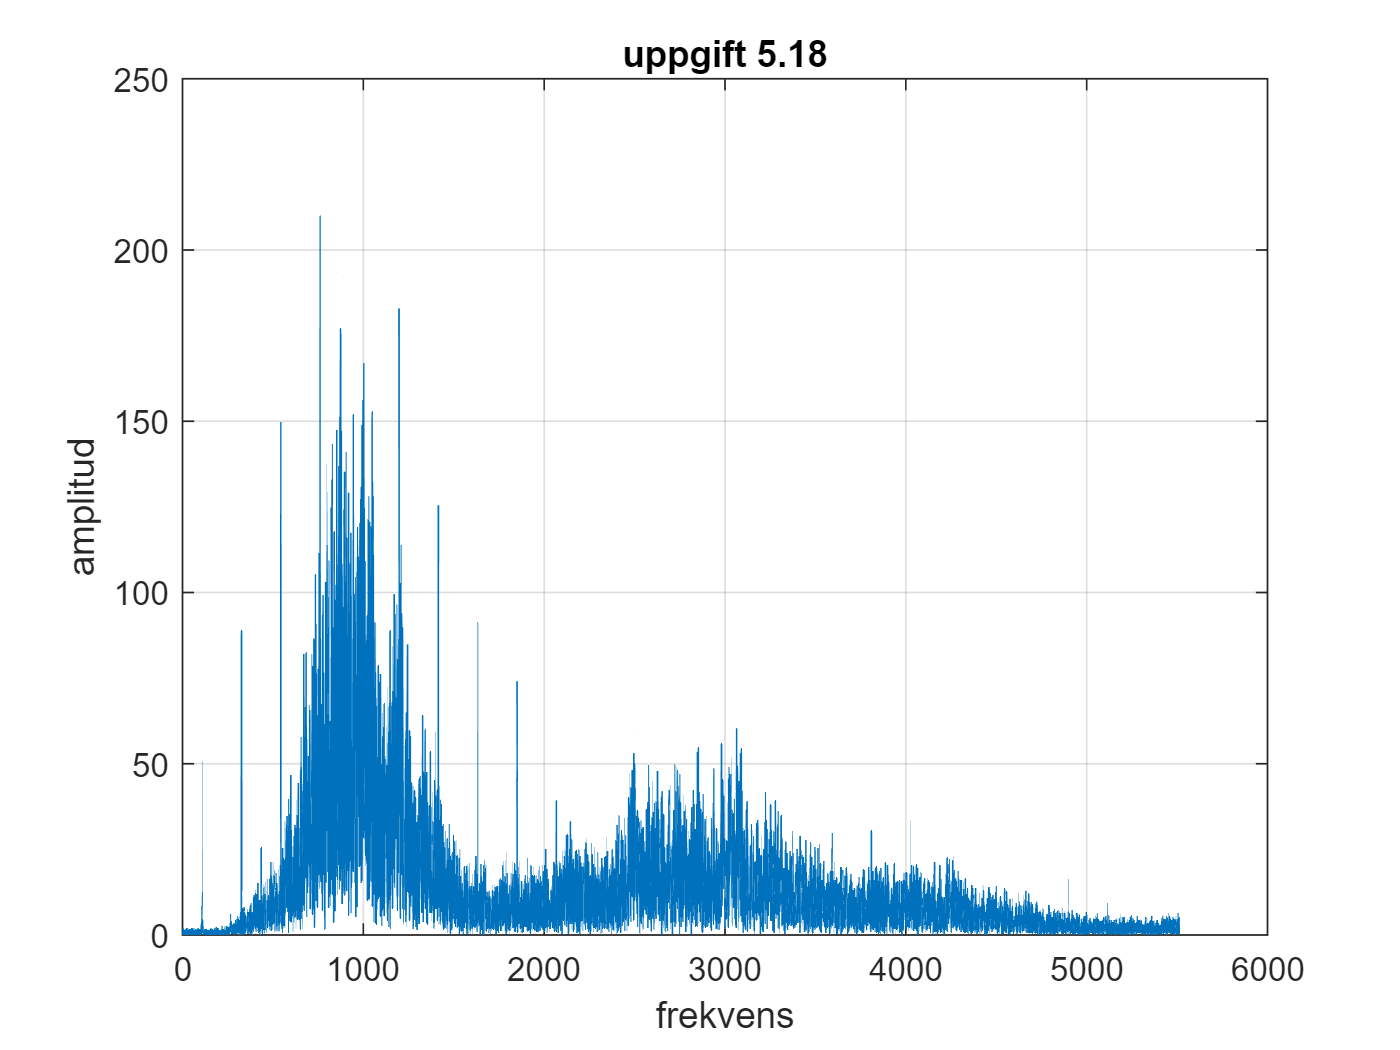

%5.18 
clear 

%läs in ljudfilen 
[x, fs] = audioread('BuzzE1.wav'); 
%lyssna på ljudfilen 
%soundsc(x, fs);

%samplingsfrekvensen 
f_sample = fs; 
%signalfrekvensen 
f_signal = fs/2; 

%skapa tidvektor för ljudspårets 5 sekunder 
t=0:(1/f_sample):5; 
%hitta mängden sampel 
N = size(t,2); 

%fouriertransformera 
X = fft2(x); 
%skapa frekvensaxel - dela med 2 för att få rätt amplitud 
f = 0:(f_sample/N):f_sample/2; 

%Hitta frekvenssteget
M = size(f,2); 

%inverse fourier transform - behövs ej för uppgiften 
%x_inv = ifft(X); 

%shift the result
x_shift = fftshift(X);

%rita resultatet
plot(f, abs(X(1:M)))
grid on;
title('uppgift 5.18')
xlabel('frekvens'); 
ylabel('amplitud');

%grafen visar att de två största topparna samlas kring frekvenserna 1000 Hz
%och 3000 Hz och har amplituder på ungefär 200 och 50 respektive 



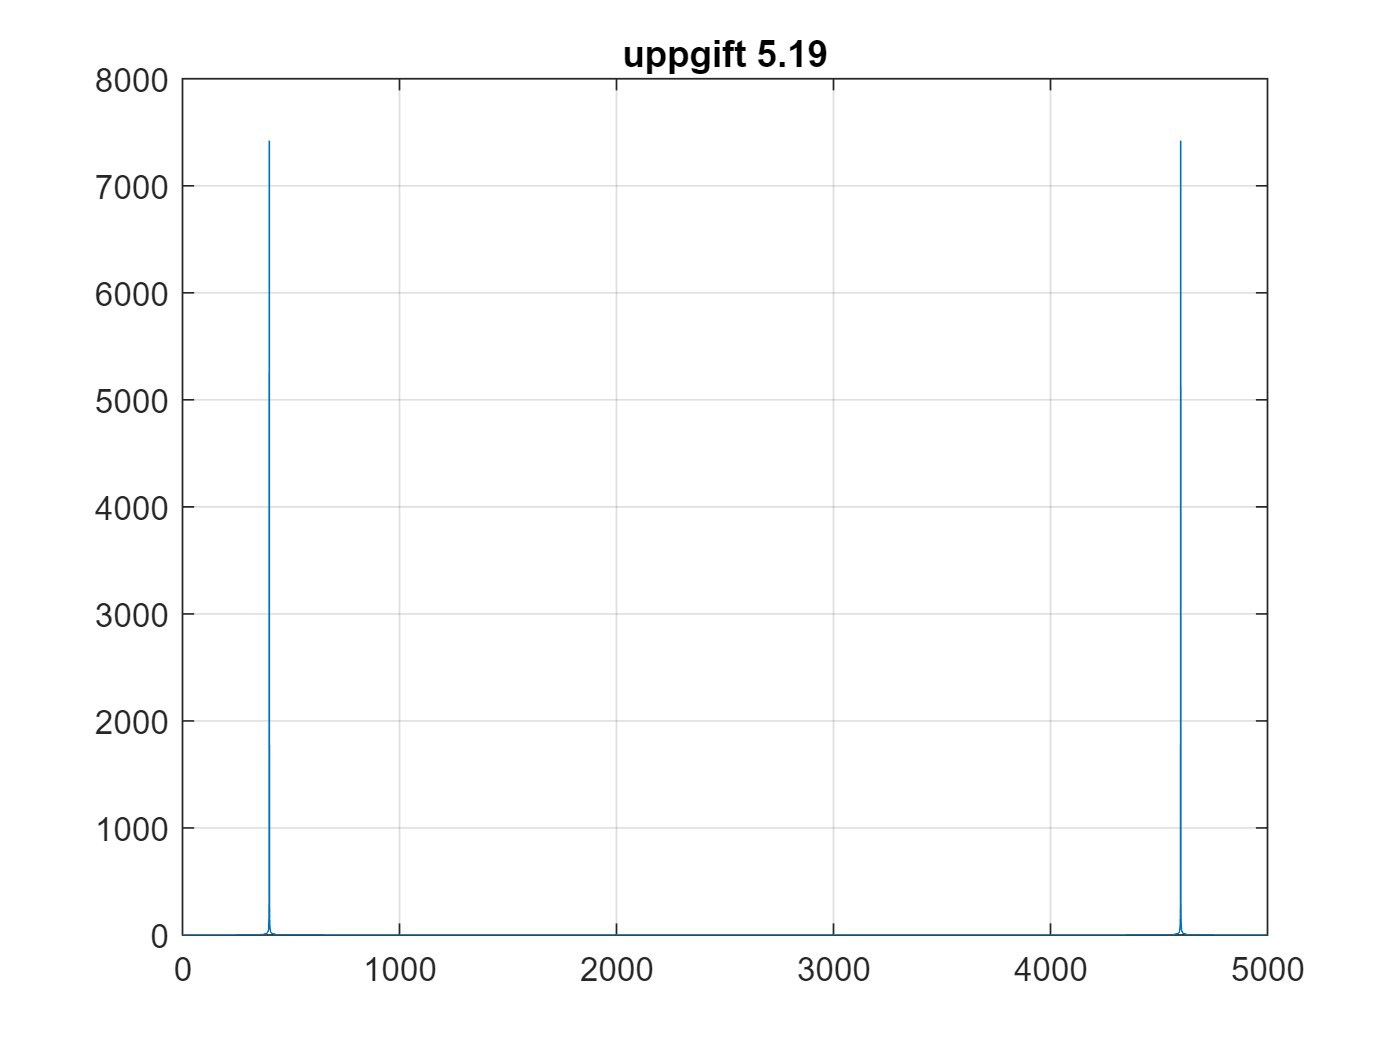

%5.19 
clear 


fs=5000; % Samplingsfrekvens

%tidvektor 
t=0:(1/fs):3;
%definiera signalen 
x=sin(2*pi*400.*t);

X=fft(x); % Utför FFT-analys

N=length(X); % Ta reda på antal värden

f=0:(fs/N):fs; % Skapa en "för lång" frekvensaxel

% dvs en som bryter mot samplingsregeln.
plot(f(1:N),abs(X(1:N))); 
grid on;
title('uppgift 5.19');

%den andra frekvenskomponenten vid ca 4800 kommer av att samplade signaler
%alltid blir periodiska, dvs x(t+2pi) = x(t), vi ser alltsp två perioder i
%grafen ovan 

%6.5 
clear
